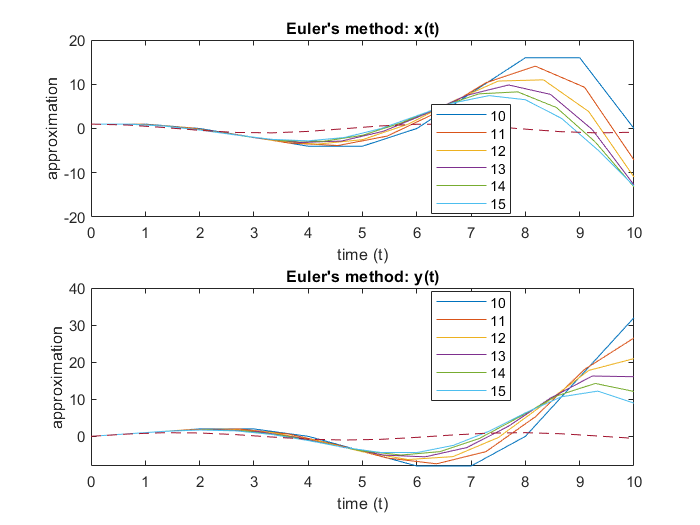

x0 = 1;
y0 = 0;
T = 10;

A = [0, -1;
    1, 0];

Ns = 10:15;

% Euler's method
figure;

subplot(2, 1, 1);
for N = Ns
    [t, x, y] = EMsolver(A, x0, y0, T, N);
    plot(t, x);
    hold on;
end
plot(t, cos(t), LineStyle="--");
legend(string(Ns), location="best");
title("Euler's method: x(t)");
xlabel("time (t)");
ylabel("approximation");

subplot(2, 1, 2);
for N = Ns
    [t, x, y] = EMsolver(A, x0, y0, T, N);
    plot(t, y);
    hold on;
end
plot(t, sin(t), LineStyle="--");
legend(string(Ns), location="best");
title("Euler's method: y(t)");
xlabel("time (t)");
ylabel("approximation");

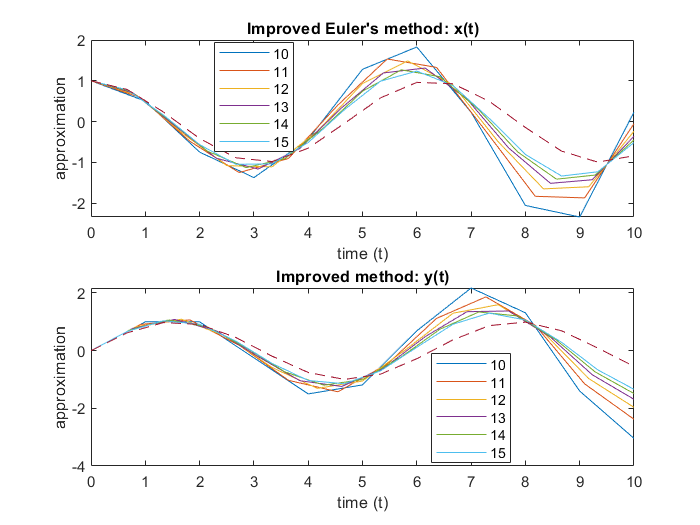


% Improved Euler's method
figure;

subplot(2, 1, 1);
for N = Ns
    [t, x, y] = IEMsolver(A, x0, y0, T, N);
    plot(t, x);
    hold on;
end
plot(t, cos(t), LineStyle="--");
legend(string(Ns), location="best");
title("Improved Euler's method: x(t)");
xlabel("time (t)");
ylabel("approximation");

subplot(2, 1, 2);
for N = Ns
    [t, x, y] = IEMsolver(A, x0, y0, T, N);
    plot(t, y);
    hold on;
end
plot(t, sin(t), LineStyle="--");
legend(string(Ns), location="best");
title("Improved method: y(t)");
xlabel("time (t)");
ylabel("approximation");

function [t, x, y] = EMsolver(A, x0, y0, T, N)
    dt = T/N;
    t = 0:dt:T;

    SOL = nan(2, length(t));
    SOL(1, 1) = x0;
    SOL(2, 1) = y0;

    for k = 2:length(t)
        zn = SOL(:, k-1);
        znp = zn + dt.*(A*zn);
        SOL(1, k) = znp(1);
        SOL(2, k) = znp(2);
    end

    x = SOL(1,:);
    y = SOL(2,:);
end

function [t, x, y] = IEMsolver(A, x0, y0, T, N)
    dt = T/N;
    t = 0:dt:T;

    SOL = nan(2, length(t));
    SOL(1, 1) = x0;
    SOL(2, 1) = y0;

    for k = 2:length(t)
        zn = SOL(:, k-1);

        znpl = A*zn;
        znpr = A*(zn + dt*znpl);

        znp = zn + dt.*((znpl + znpr)/2);
        
        SOL(1, k) = znp(1);
        SOL(2, k) = znp(2);
    end

    x = SOL(1,:);
    y = SOL(2,:);
end